Colin Keenan

ECE 5470

4-7-2020

# Homework 8

1.  Converting Colors

clear

fprintf("Question 1:")

Question 1:

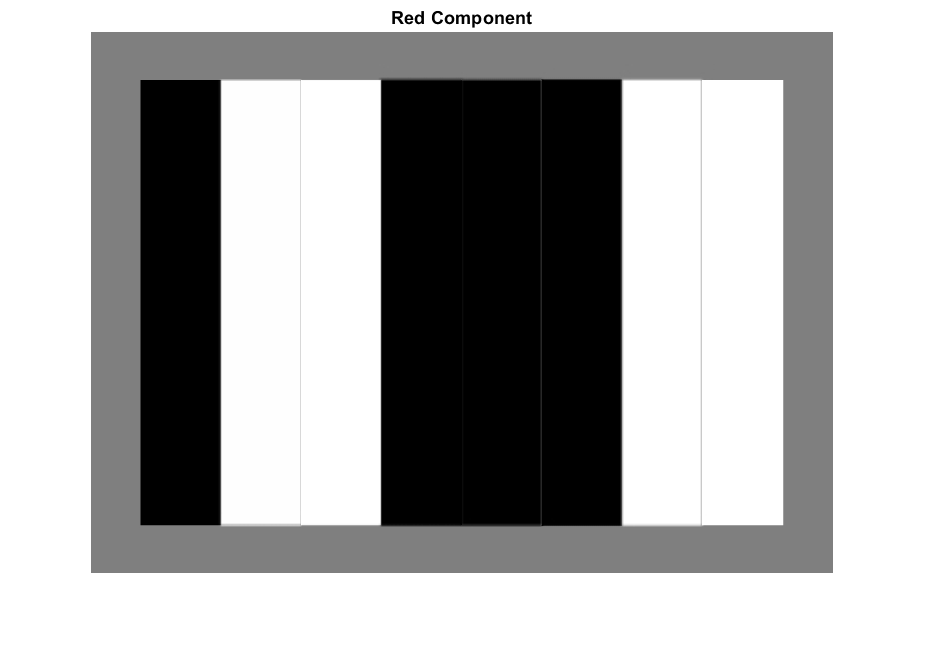


image = im2double(imread('Fig5-1.jpg'));

% RGB Display
R = image(:,:,1);
G = image(:,:,2);
B = image(:,:,3);

figure();
imshow(R);
title("Red Component")

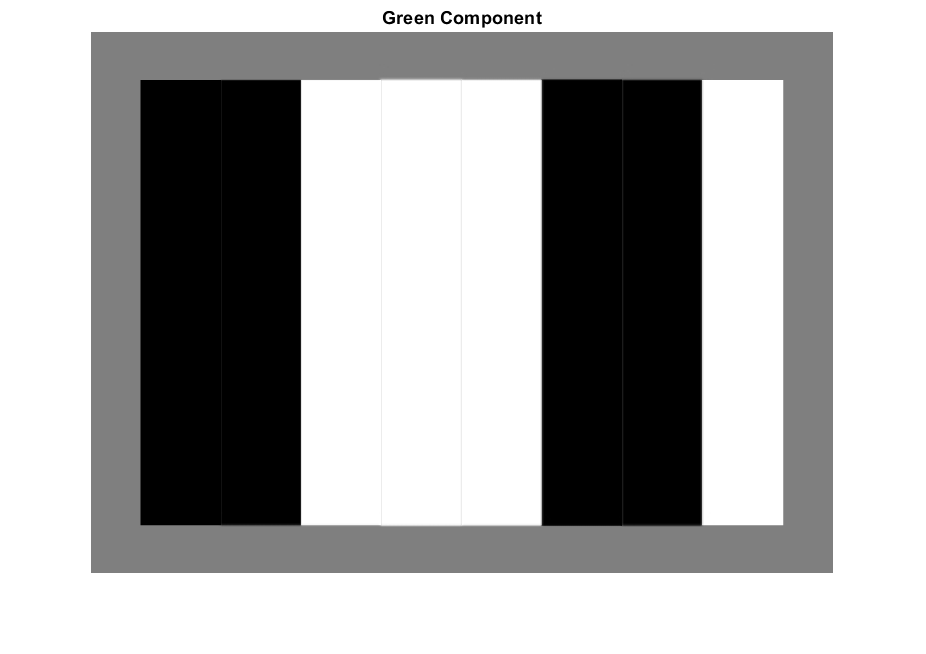

figure();
imshow(G);
title("Green Component")

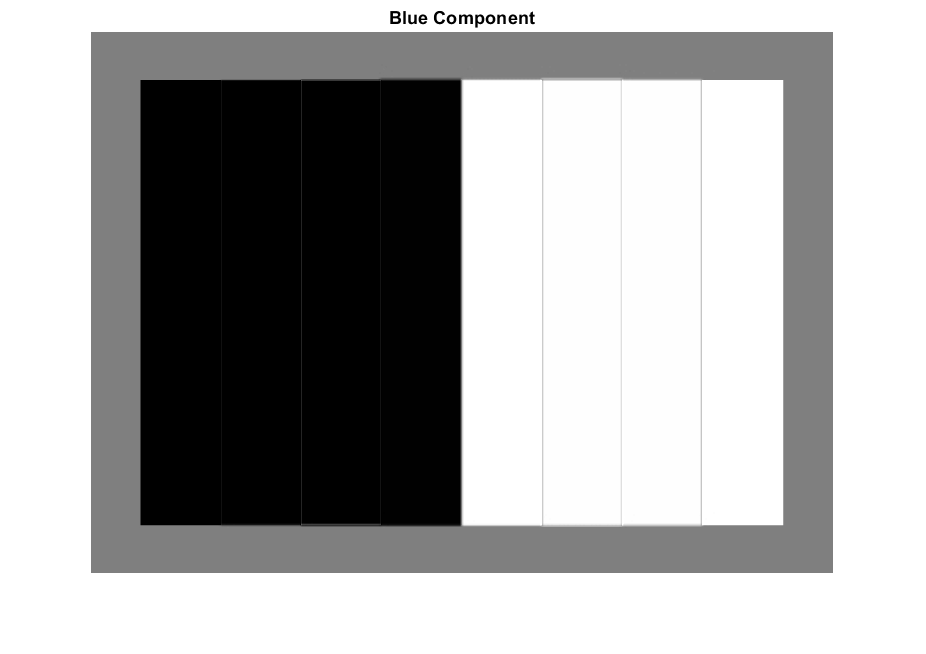

figure();
imshow(B);
title("Blue Component")

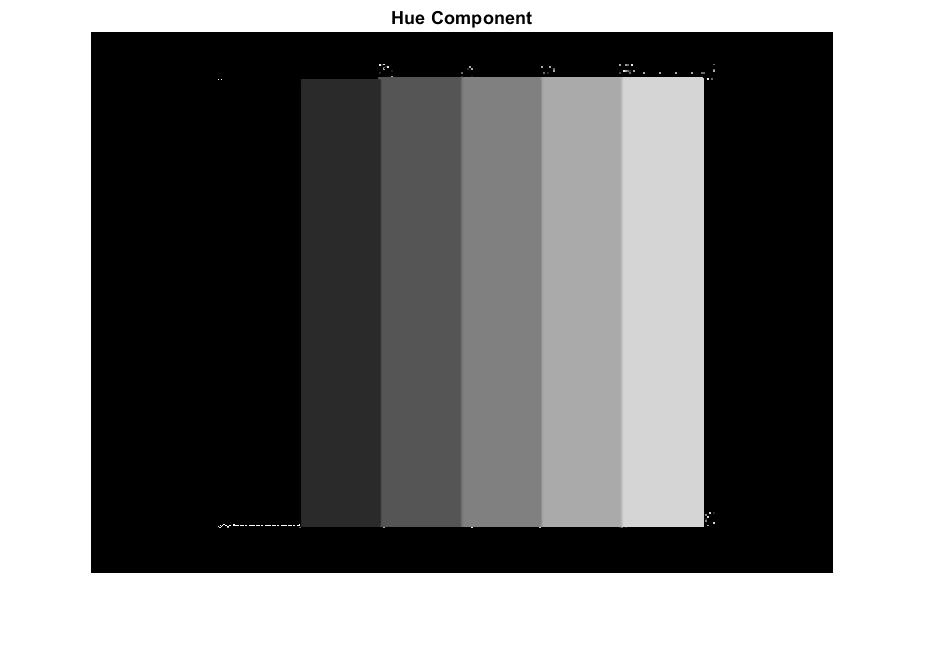


% RGB to HSI Display
[H,S,I] = rgb2hsi(R,G,B);

figure();
imshow(H);
title("Hue Component")

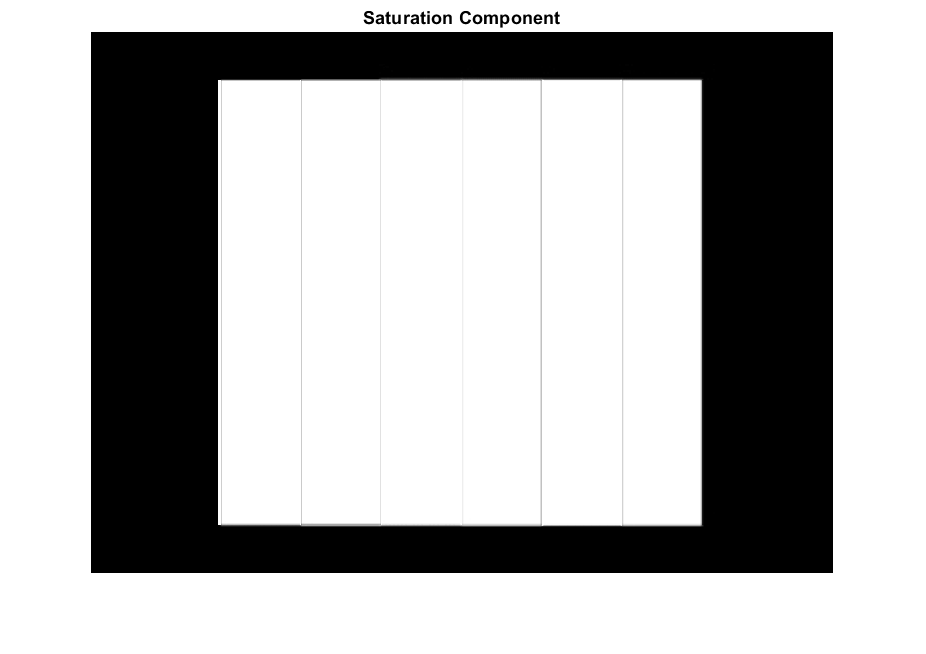

figure();
imshow(S);
title("Saturation Component")

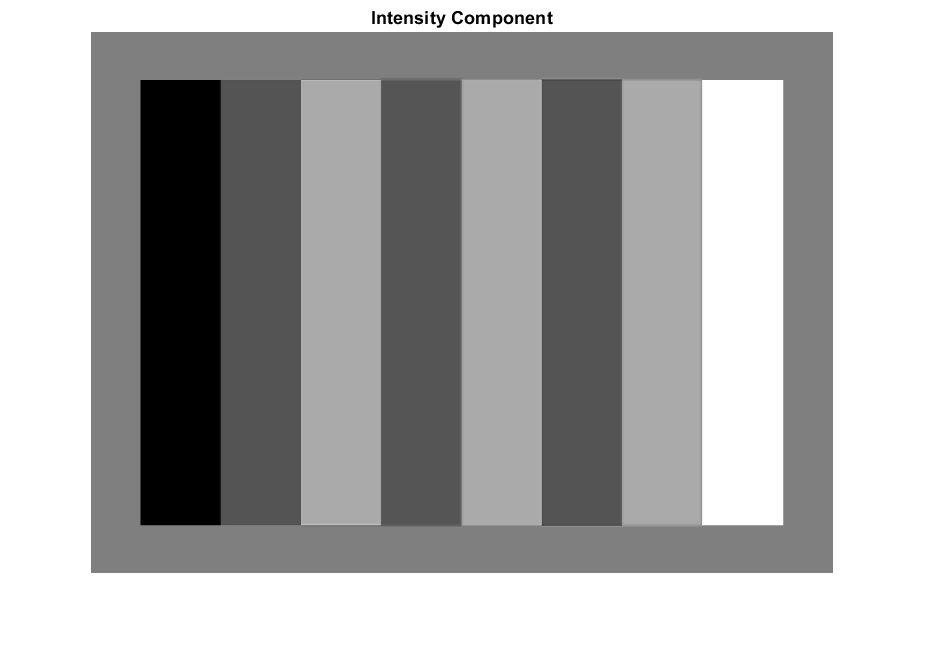

figure();
imshow(I);
title("Intensity Component")

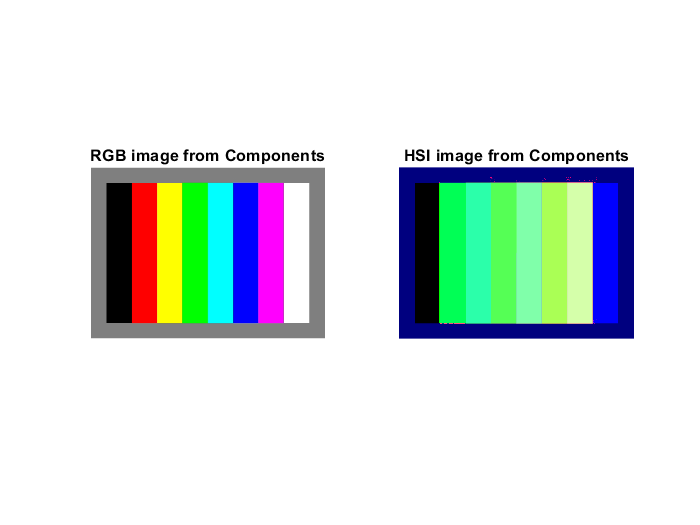


% Compare HSI and RGB Components
RGB(:,:,1) = R;
RGB(:,:,2) = G;
RGB(:,:,3) = B;

HSI(:,:,1) = H;
HSI(:,:,2) = S;
HSI(:,:,3) = I;

figure();
subplot(1,2,1);
imshow(RGB);
title("RGB image from Components");
subplot(1,2,2);
imshow(HSI);
title("HSI image from Components");

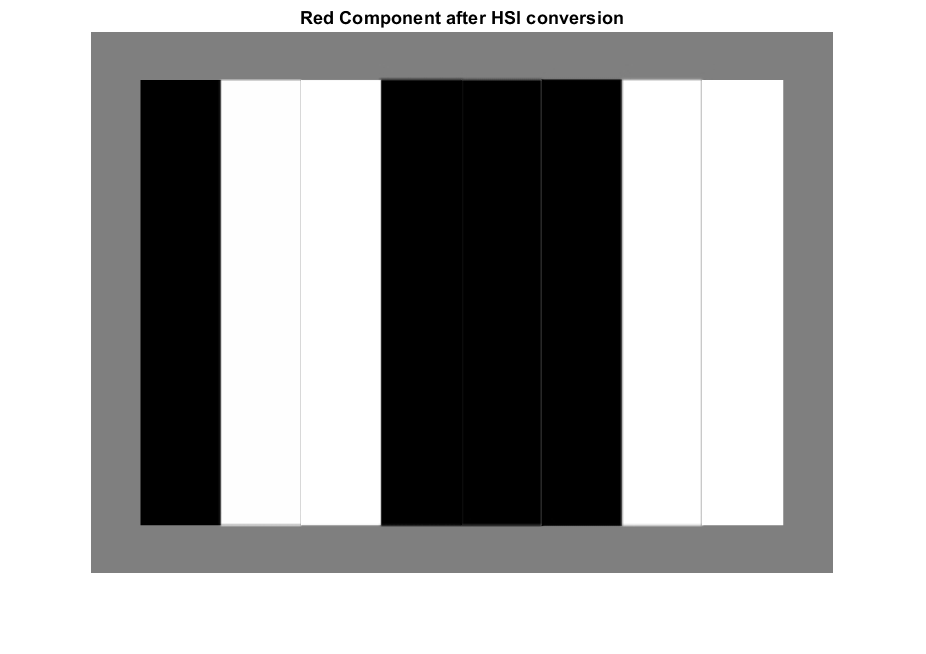


% HSI to RGB Display
[Rn,Gn,Bn] = hsi2rgb(H,S,I);

figure();
imshow(Rn);
title("Red Component after HSI conversion")

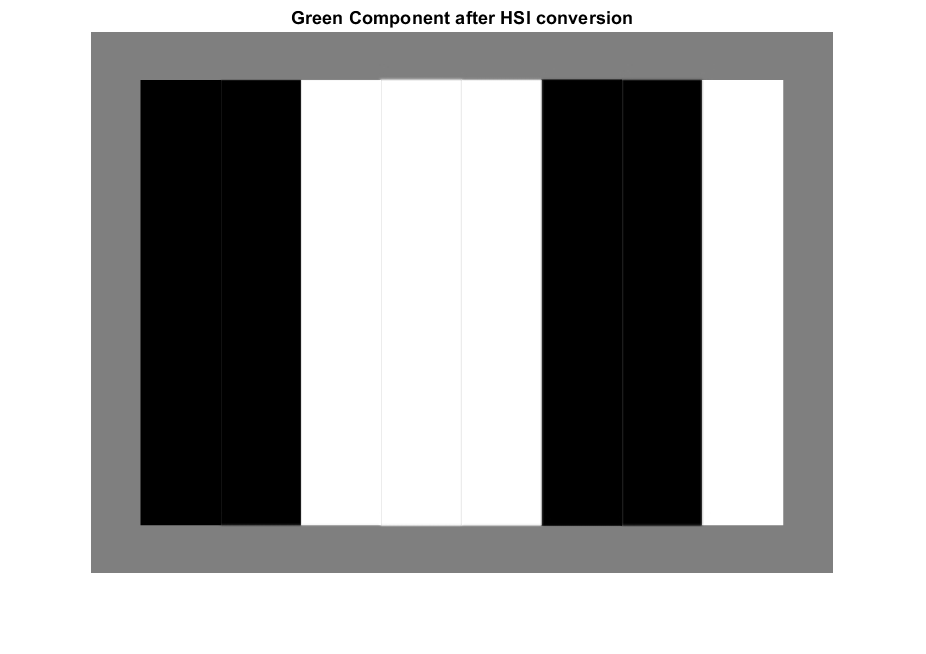

figure();
imshow(Gn);
title("Green Component after HSI conversion")

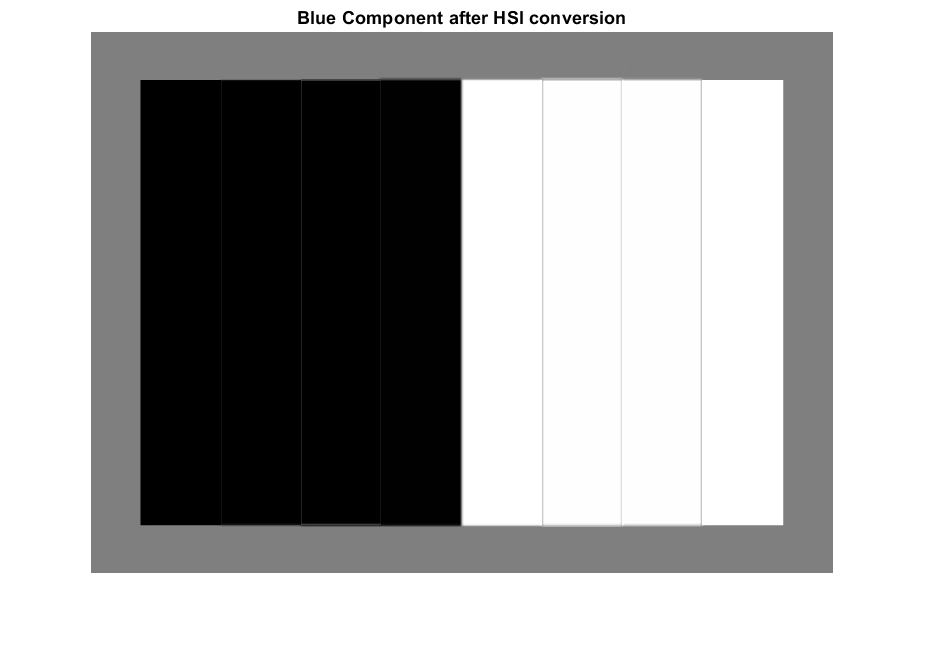

figure();
imshow(Bn);
title("Blue Component after HSI conversion")

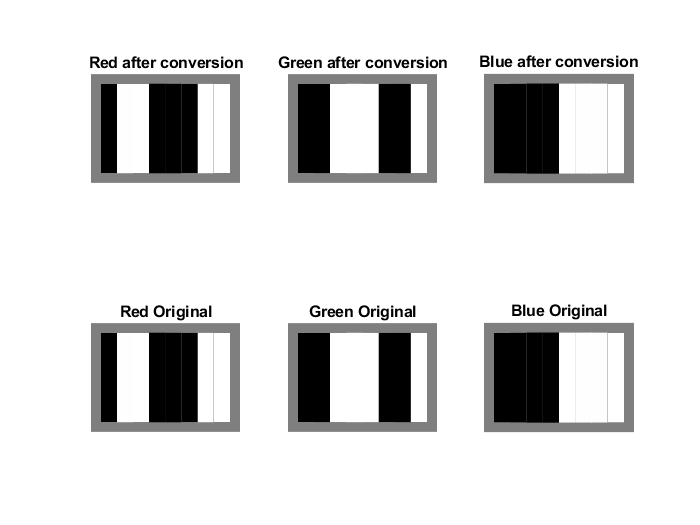


% Compare old and new RGB components
figure();
subplot(2,3,1)
imshow(Rn);
title("Red after conversion")
subplot(2,3,2)
imshow(Gn);
title("Green after conversion")
subplot(2,3,3)
imshow(Bn);
title("Blue after conversion")
subplot(2,3,4)
imshow(R);
title("Red Original")
subplot(2,3,5)
imshow(G);
title("Green Original")
subplot(2,3,6)
imshow(B);
title("Blue Original")

Explanation: As you can see in the comparison subplot at the end, the RGB conversion after the RGB to HSI conversion restored the image perfectly.

2. Pseudocolor Image Processing

clear

fprintf("Question 2:")

Question 2:

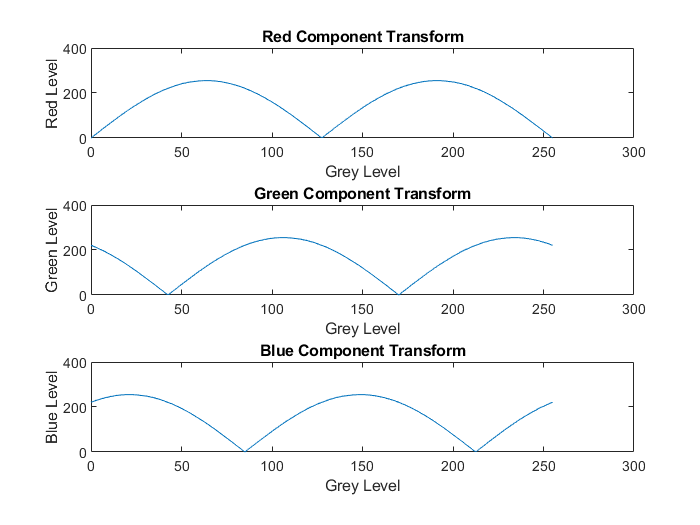


image = imread('Fig5-2.jpg');

x = 0:255;
tranR = round(abs(255*sin((2*pi)/255 * x - 0)));
tranG = round(abs(255*sin((2*pi)/255 * x - pi/3)));
tranB = round(abs(255*sin((2*pi)/255 * x - 2*pi/3)));

figure();
subplot(3,1,1);
plot(x,tranR);
xlabel('Grey Level');
ylabel('Red Level');
title('Red Component Transform');
xlim([0 300]);
ylim([0 400]);
subplot(3,1,2);
plot(x,tranG);
xlabel('Grey Level');
ylabel('Green Level');
title('Green Component Transform');
xlim([0 300]);
ylim([0 400]);
subplot(3,1,3);
plot(x,tranB);
xlabel('Grey Level');
ylabel('Blue Level');
title('Blue Component Transform');
xlim([0 300]);
ylim([0 400]);

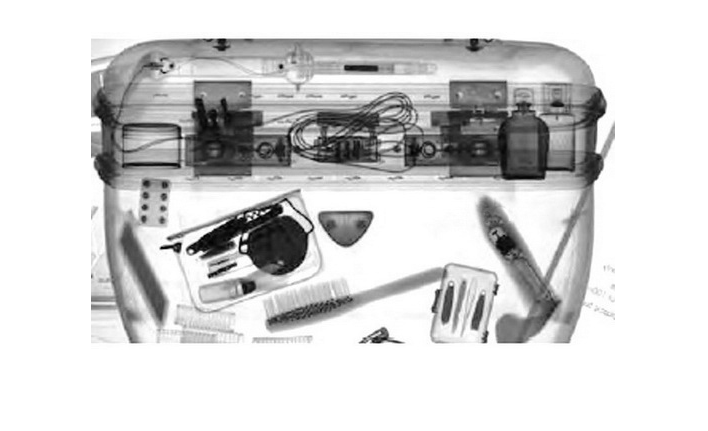


R = zeros(size(image));
G = zeros(size(image));
B = zeros(size(image));

for x = 1:size(image,1)
    for y = 1:size(image,2)
        R(x,y) = tranR(image(x,y)+1);
        G(x,y) = tranG(image(x,y)+1);
        B(x,y) = tranB(image(x,y)+1);
    end
end

RGB(:,:,1) = R/255;
RGB(:,:,2) = G/255;
RGB(:,:,3) = B/255;

figure();
imshow(image);

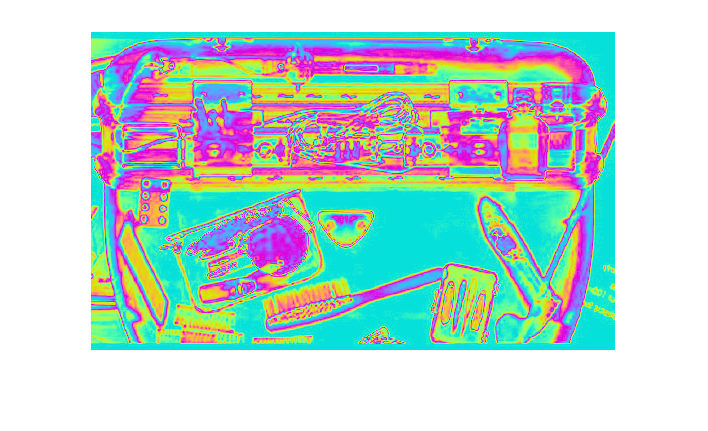

figure();
imshow(RGB);

3.  Tone and Color Correction

clear

fprintf("Question 3:")

Question 3:

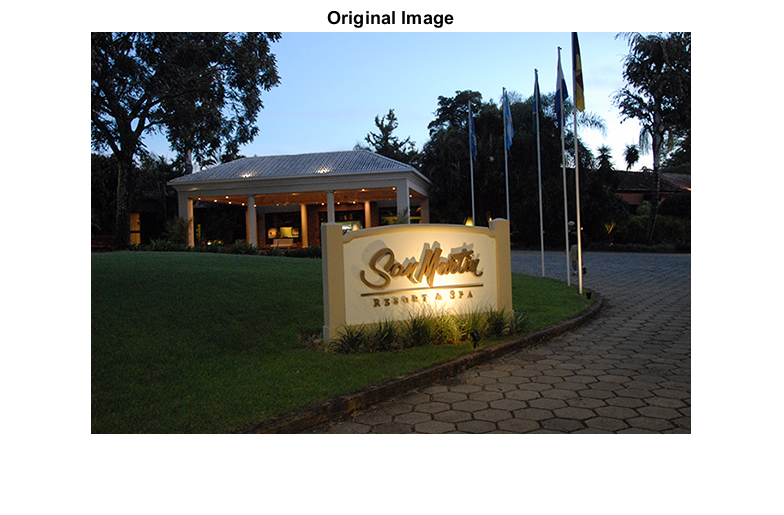


image = im2double(imread('Fig5-3.jpg'));

c = 1;      % c values from 0 to 10 with step size of 1
y = 0.4;    % gamma values from 0 to 25 with step size of 0.01

x = 1:256;
transform = c*(x.^y);

RGB = zeros(size(image));
[H,S,I] = rgb2hsi(image(:,:,1), image(:,:,2), image(:,:,3));

for i = 1:size(image,1)
    for j = 1:size(image,2)
        RGB(i,j,1) = c * (image(i,j,1)^y);
        RGB(i,j,2) = c * (image(i,j,2)^y);
        RGB(i,j,3) = c * (image(i,j,3)^y);
        
        I(i,j) = c * (I(i,j)^y);
    end
end

[R,G,B] = hsi2rgb(H,S,I);
HSI(:,:,1) = R;
HSI(:,:,2) = G;
HSI(:,:,3) = B;

figure();
imshow(image);
title('Original Image');

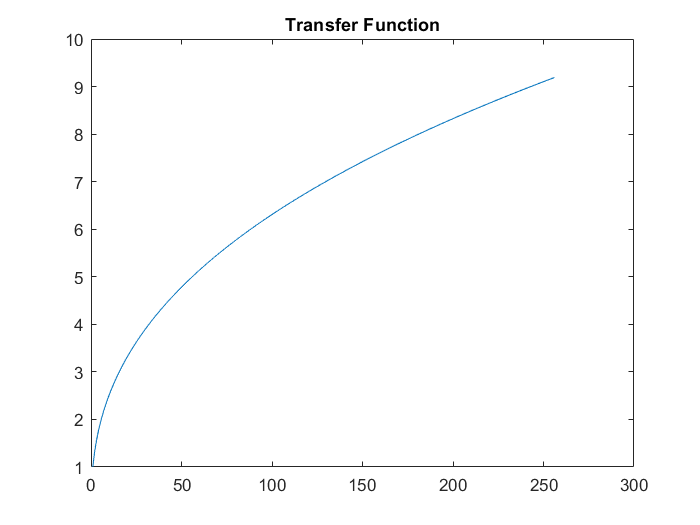

figure();
plot(x,transform);
title('Transfer Function');

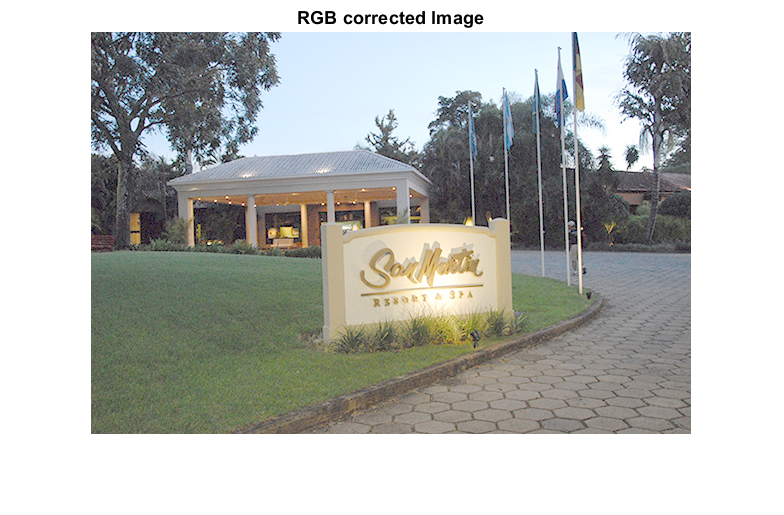

figure();
imshow(RGB);
title('RGB corrected Image');

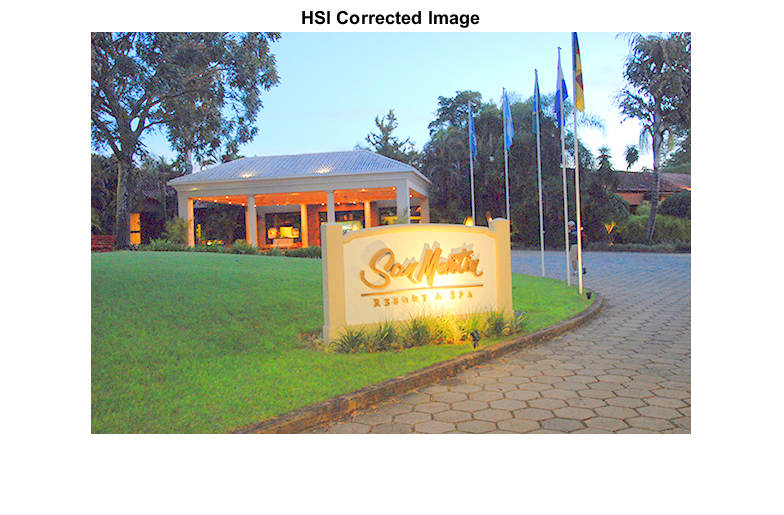

figure();
imshow(HSI);
title('HSI Corrected Image');

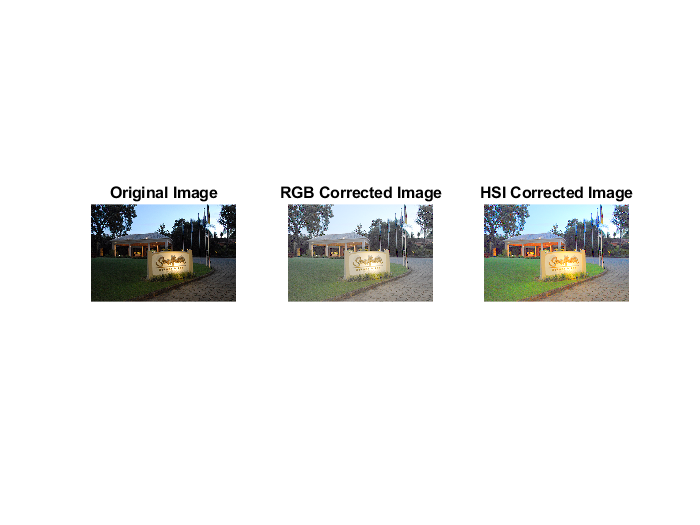

figure();
subplot(1,3,1)
imshow(image);
title('Original Image');
subplot(1,3,2)
imshow(RGB);
title('RGB Corrected Image');
subplot(1,3,3)
imshow(HSI);
title('HSI Corrected Image');

Explanation: Given the same power-law transform, when applied to HSI, only the Intensity is affected and in my opinion results in a better image and avoid washing out the colors, at the cost of color accuracy, since the image is now much more saturated. When transforming the RGB portion, the color accuracy is maintaned better, but has an overall "washed-out" look.

## **Appendix (Functions Used)**

function [H,S,I] = rgb2hsi(R,G,B)
    H = zeros(size(R));
    S = zeros(size(R));
    I = zeros(size(R));
    for x = 1:size(R,1)
        for y = 1:size(R,2)
            % Get RGB values for the given pixel
            Ri = R(x,y);
            Gi = G(x,y);
            Bi = B(x,y);
            
            % Calculate H
            num = 0.5*((Ri-Gi) + (Ri-Bi));
            den = sqrt(((Ri-Gi)^2 + (Ri-Bi)*(Gi-Bi)));
            theta = acos(num/den);
            thetaD = theta * (180/pi);
            
            if(Bi <= Gi)
                H(x,y) = thetaD;
            elseif(Bi > Gi)
                H(x,y) = 360 - thetaD;
            else
                print("error occurred in RGB to HSI processing")
            end
            
            % Calculate S
            S(x,y) = 1 - (((3)/(Ri+Gi+Bi)) * min([Ri Gi Bi]));
            
            % Calculate I
            I(x,y) = (1/3) * (Ri+Gi+Bi);
            
            if((Ri==Gi) && (Gi == Bi))
                H(x,y) = 0;
                S(x,y) = 0;
            end
            H(x,y) = H(x,y)/360;
        end
    end
end

function [R,G,B] = hsi2rgb(H,S,I)
    R = zeros(size(H));
    G = zeros(size(H));
    B = zeros(size(H));
        
    for x = 1:size(H,1)
        for y = 1:size(H,2)
            % Get HSI values for the given pixel
            Hi = H(x,y) * 360;
            Si = S(x,y);
            Ii = I(x,y);
            
            if((Hi >= 0) && (Hi <= 120))
                B(x,y) = Ii*(1-Si);
                R(x,y) = Ii * (1 + ((Si * cosd(Hi))/(cosd(60 - Hi))));
                G(x,y) = 3*Ii - (R(x,y)+B(x,y));
                
            elseif((Hi >= 120) && (Hi <= 240))
                Hi = Hi - 120;
                R(x,y) = Ii*(1-Si);
                G(x,y) = Ii * (1 + ((Si * cosd(Hi))/(cosd(60 - Hi))));
                B(x,y) = 3*Ii - (R(x,y)+G(x,y));
                
            elseif((Hi >= 240) && (Hi <= 360))
                Hi = Hi - 240;
                G(x,y) = Ii*(1-Si);
                B(x,y) = Ii * (1 + ((Si * cosd(Hi))/(cosd(60 - Hi))));
                R(x,y) = 3*Ii - (G(x,y)+B(x,y));
                
            end
        end
    end
end
